
xmin=42;
xmax=74;
ymin=38;
ymax=63;
mask=zeros(100,100);
mask(xmin:xmax,ymin:ymax)=1;


[OD,noise_OD,SNRGain]=FringeReduction('\\Artemis-pc\e\Data\2022-12-24\Abs-3550',4,70,4,xmin,ymin,xmax,ymax);
figure
t=tiledlayout(2,2)

t =   TiledChartLayout - 属性:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  显示 所有属性


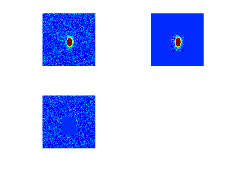

nexttile(1)
imshow(OD)
set(gca,'Clim',[-0.1 0.5])
colormap jet
nexttile(2)
imshow(mask.*OD)
set(gca,'Clim',[-0.1 0.5])
colormap jet
nexttile(3)
imshow((1-mask).*OD)
set(gca,'Clim',[-0.1 0.5])
colormap jet

sum(sum(OD))

ans = 131.0042

sum(sum(mask.*OD))

ans = 132.5706

sum(sum((1-mask).*OD))

ans = -1.5665

% 96-311

data_start=96;
data_end=3551;

parfor i=1:(data_end-data_start)+1
    [OD1,ODraw1]=FringeReduction(['\\Artemis-pc\e\Data\2022-12-24\Abs-',num2str(data_start+i-1)],2,70,4,xmin,ymin,xmax,ymax);
    [OD2,ODraw2]=FringeReduction(['\\Artemis-pc\e\Data\2022-12-24\Abs-',num2str(data_start+i-1)],3,70,4,xmin,ymin,xmax,ymax);
    [OD3,ODraw3]=FringeReduction(['\\Artemis-pc\e\Data\2022-12-24\Abs-',num2str(data_start+i-1)],4,70,4,xmin,ymin,xmax,ymax);
    OD_all_1(i)=sum(sum(OD1));
    OD_all_2(i)=sum(sum(OD2));
    OD_all_3(i)=sum(sum(OD3));0
    OD_roi_1(i)=sum(sum(mask.*OD1));
    OD_roi_2(i)=sum(sum(mask.*OD2));
    OD_roi_3(i)=sum(sum(mask.*OD3));
    OD_n_roi_1(i)=sum(sum((1-mask).*OD1));
    OD_n_roi_2(i)=sum(sum((1-mask).*OD2));
    OD_n_roi_3(i)=sum(sum((1-mask).*OD3));

    OD_all_1_raw(i)=sum(sum(ODraw1));
    OD_all_2_raw(i)=sum(sum(ODraw2));
    OD_all_3_raw(i)=sum(sum(ODraw3));
    OD_roi_1_raw(i)=sum(sum(mask.*ODraw1));
    OD_roi_2_raw(i)=sum(sum(mask.*ODraw2));
    OD_roi_3_raw(i)=sum(sum(mask.*ODraw3));
    OD_n_roi_1_raw(i)=sum(sum((1-mask).*ODraw1));
    OD_n_roi_2_raw(i)=sum(sum((1-mask).*ODraw2));
    OD_n_roi_3_raw(i)=sum(sum((1-mask).*ODraw3));
end


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =

     0


ans =



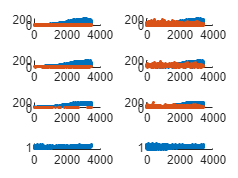

figure

%scatter(1:length(OD_all),OD_all)
tiledlayout(4,2)
nexttile(1)
hold all
scatter(1:length(OD_all_1),OD_roi_1,'.')
scatter(1:length(OD_all_1),OD_n_roi_1,'.')
ylim([-5 200])
nexttile(3)
hold all
scatter(1:length(OD_all_1),OD_roi_2,'.')
scatter(1:length(OD_all_1),OD_n_roi_2,'.')
ylim([-5 200])
nexttile(5)
hold all
scatter(1:length(OD_all_1),OD_roi_3,'.')
scatter(1:length(OD_all_1),OD_n_roi_3,'.')
ylim([-5 200])
nexttile(7)
hold all
scatter(1:length(OD_all_1),(OD_roi_1+OD_roi_2)./(OD_roi_3),'.')
ylim([0.5 1.5])

nexttile(2)
hold all
scatter(1:length(OD_all_1),OD_roi_1_raw,'.')
scatter(1:length(OD_all_1),OD_n_roi_1_raw,'.')
ylim([-5 200])
nexttile(4)
hold all
scatter(1:length(OD_all_1),OD_roi_2_raw,'.')
scatter(1:length(OD_all_1),OD_n_roi_2_raw,'.')
ylim([-5 200])
nexttile(6)
hold all
scatter(1:length(OD_all_1),OD_roi_3_raw,'.')
scatter(1:length(OD_all_1),OD_n_roi_3_raw,'.')
ylim([-5 200])
nexttile(8)
hold all
scatter(1:length(OD_all_1),(OD_roi_1_raw+OD_roi_2_raw)./(OD_roi_3_raw),'.')
ylim([0.5 1.5])


mean((OD_roi_1+OD_roi_2)./(OD_roi_3))

ans = 0.9860

std((OD_roi_1+OD_roi_2)./(OD_roi_3))

ans = 0.0872

p=(OD_roi_1+OD_roi_2)./(OD_roi_3);
p_raw=(OD_roi_1_raw+OD_roi_2_raw)./(OD_roi_3_raw);
mean((OD_roi_1_raw+OD_roi_2_raw)./(OD_roi_3_raw))

ans = 0.9974

std((OD_roi_1_raw+OD_roi_2_raw)./(OD_roi_3_raw))

ans = 0.1800

xxxx=1:length(OD_all_1);

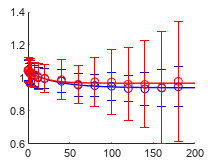

precess_2_list=fliplr([0,1.1:1.1:4.4,8,12,20:20:180]);


errorbar(precess_2_list,mean(reshape(p,216,16)),std(reshape(p,216,16)),'o','Color','blue')
errorbar(precess_2_list,mean(reshape(p_raw,216,16)),std(reshape(p_raw,216,16)),'o','Color','red')


figure
hold all
eqn='a*exp(-x^1/b^1)+c';
startpoints=[0.5 1 1];
lower=[0 0 0];
upper=[1.1 2000000 1];


fi_pop_coherent=fit(precess_2_list',mean(reshape(p,216,16))',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./std(reshape(p,216,16)).^2);
plot((0:1:200),fi_pop_coherent(0:1:200)./(fi_pop_coherent.a+fi_pop_coherent.c),'LineWidth',1,'Color','blue');
errorbar(precess_2_list,mean(reshape(p,216,16))./(fi_pop_coherent.a+fi_pop_coherent.c),std(reshape(p,216,16)),'o','Color','blue')
fi_pop_coherent.a+fi_pop_coherent.c

ans = 1.0377

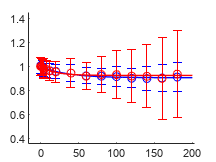


fi_pop_coherent=fit(precess_2_list',mean(reshape(p_raw,216,16))',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./std(reshape(p_raw,216,16)).^2);
plot((0:1:200),fi_pop_coherent(0:1:200)./(fi_pop_coherent.a+fi_pop_coherent.c),'LineWidth',1,'Color','red');
errorbar(precess_2_list,mean(reshape(p_raw,216,16))./(fi_pop_coherent.a+fi_pop_coherent.c),std(reshape(p_raw,216,16)),'o','Color','red')

fi_pop_coherent.a+fi_pop_coherent.c

ans = 1.0457